# Linear Control Design 2 - Fall 2022 - Exam Part I

## Introduction

The Part I of the Exam in Linear Control Design 2 (E22) consists of numerical exercises testing the acquisition of competences in the areas of analysis and design of control systems using modern control theory based on state space representation of system dynamics.

**The scoring of each problem is clearly stated.** 

It is the sole responsability of the student to guarantee that the solution delivered for evaluation can be run by the examiner without the need of contacting the student. All dependencies on files external to this Matlab Live Script must be checked and included in the final delivery. **If the examiner will not be able to execute the Matlab Live Script delivered as solution by the student, the Part I will be considered failed.** 

% Fill in your information
Exam = 'LCD2 E22'

Exam = 'LCD2 E22'

Student_Name = 'Student Name'

Student_Name = 'Student Name'

Student_Number = 'Student Number'

Student_Number = 'Student Number'

## Optimal output feedback control of a balance system

A balance system is a mechanical system in which the center of mass is balanced above a pivot point. A popular example of a balance system is the Segway Personal Transporter (shown in the figure below) where a motorized platform is used to stabilize the person standing on top of it. Balance systems are a generalization of a mass-spring-damper system to multi-degree-of-freedom, and the inverted pendulum on a cart (also shown in the figure below) is a good mechanical approximation of such systems.

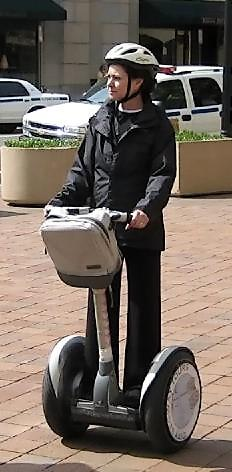            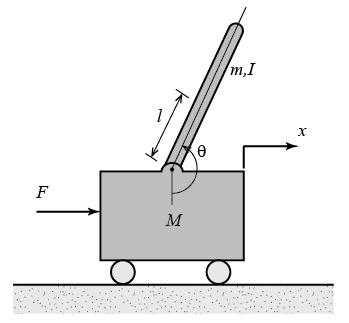

For this system the control input is the force $F$ that moves the cart in the longitudinal direction, and the measured output is the longitudinal position $x$ of the cart. The control objective is to keep the pendulum in its uprigth position ($\theta = \pi$rad) while moving the cart along the longitudinal direction. This is equivalent to the Segway Personal Transporter keeping its upright position while the rider leans forward to move along the ground. 

### Nonlinear model of the inverted pendulum on a cart

The nonlinear model describing the dynamical variations of the angular position of the pendulum $\theta$ and the linear position of the cart $x$ is described by the following nonlinear coupled second order differential equations

$(I + ml^2)\ddot{\theta} + c\dot{\theta} +mgl\sin\theta = -ml\ddot{x}\cos\theta  \\
(M+m)\ddot{x}+b\dot{x}+ml\ddot{\theta}\cos \theta-ml\dot{\theta}^2 \sin \theta = F \\
y = x$       (1)

where

- $M$is the mass of the cart

- $m$ is the mass of the pendulum

- $I$ is the inertia of the pendulum

- $b$ is the viscous friction coefficient of the cart

- $c$ is the viscous friction coefficient of the pendulum

- $l$ is the lenght of the pendulum

- $g$ is the gravitational constant 

The nonlinear model in Eq. (1) is implemented in the Simulink file InvertedPendulum_SimulinkYYYYC, where YYYYC refers to the Simulink version (2021b, 2021a, 2020b, 2020a, 2019b, 2019a, 2018b, 2018a, 2017b, 2017a). The numerical values for the model parameters are provided right below.

% Model paramters (RG)
% Prepare the workspace
clear all
clc
load zero2
x_meas = x;
theta_meas = deg2rad(theta);
x_meas = x_meas(fix(1.5/0.001):end);
theta_meas = theta_meas(fix(1.5/0.001):end);
t = t(1:length(theta_meas));

% System parameters
M = 0.632; % mass of trolley [kg]
m = 0.181; % mass of pendulum bob [kg]
b = 0.1; % friction coefficient trolley [kg/s]
c = 0.01; % friction coefficient pendulum [kg*m^2/s]
bc = b;
bp = c;
g = 9.8; % gravity constant [m/s^2]
l = 0.365/2; % lenght of pendulum rod [m]
L = 0.365/2;
I = 1/12*m*(2*L)^2; % inertia of pendulum [kg*m^2]
Jp = I;
Rm = 3.3;
Lm = 1.25e-3;
kt = 0.0491;
ke = kt;
Jm = 1.55e-5;
bm = 9.25e-6;
r = 26.5e-3/2;

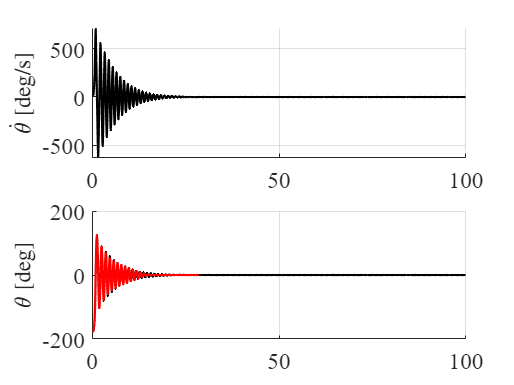


% Initial conditions for testing the Simulink model (RG)
theta_dot0 = 0; % pendulum angular velocity [rad/s]
theta0 = theta_meas(1); % pendulum angular position [rad]
x_dot0 = 0; % trolley linear velocity [m/s]
x0 = 0; % trolley linear position [m]
F0 = 0; % linear force applied to the trolley [N]

% Test the provided inverted pendulum model (RG)
SIM_TIME = 100; % simulation time (can be changed as needed - if simulated for longer time, the pendulum returns to the downward position)
STEP_SIZE = 0.001; % integration step size of Simulink (can be changed as needed)
% Change with the name of the model you are using
SIMULINK_FILENAME = 'mymod';
time = (0:STEP_SIZE:SIM_TIME)';
F_ctrl = F0*ones(length(time),1);
sim(SIMULINK_FILENAME,SIM_TIME,[],[time F_ctrl])

% Plot the temporal behaviour of the quantities of interest (RG)
theta_dot = rad2deg(logsout.getElement('theta_dot').Values.Data);
theta = wrapTo180(rad2deg(logsout.getElement('theta').Values.Data)); % the pendulum angular position is wrapped between -180 and 180 degress
x_dot = logsout.getElement('x_dot').Values.Data;
x = logsout.getElement('x').Values.Data;

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta_dot,'k','LineWidth',1.5)
ylabel('$\dot{\theta}$ [deg/s]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,theta,'k','LineWidth',1.5)
plot(t, theta_meas*180/pi,'r','LineWidth',1.5)
ylabel('$\theta$ [deg]','FontName','times','FontSize',16,'Interpreter','latex')

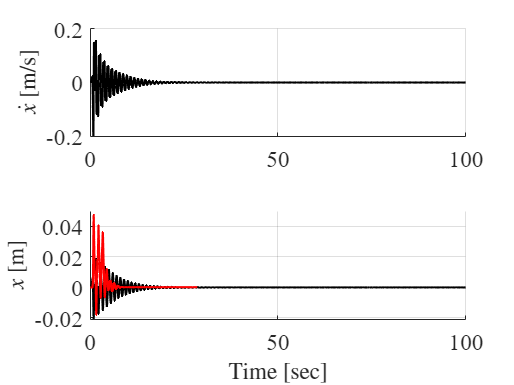

figure, h1 = subplot(2,1,1); set(h1,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x_dot,'k','LineWidth',1.5)
ylabel('$\dot{x}$ [m/s]','FontName','times','FontSize',16,'Interpreter','latex')
h2 = subplot(2,1,2); set(h2,'FontName','times','FontSize',16)
hold on, grid on
plot(time,x,'k','LineWidth',1.5)
plot(t, x_meas,'r','LineWidth',1.5)
ylabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('Time [sec]','FontName','times','FontSize',16,'Interpreter','latex')

### Open-loop system analysis

**Problem 1 [2 points]** Based on the system dynamics described in Eq. (1), determine the system state vector, input, disturbance and output. Exploiting the Simulink model InvertedPendulum_SimulinkYYYYC linearize the system about the following operating point: $\theta = \pi \, \mathrm{rad}; \, \dot{\theta}= 0\, \mathrm{rad/s}; \, x = 0\,\mathrm{m}; \, \dot{x} = 0\, \mathrm{m/s}$.

[A, B, C, D] = linmod(SIMULINK_FILENAME, [0;pi;0;0], 0, 0);

ss_ol = ss(A, B, C, D);





**Problem 2 [2 points]** Evaluate the internal and the external stability of system.

% Your solution goes here
lbds = eig(A(1:4,1:4))

lbds =          0
    6.4492
   -6.0559
  -18.0132


**Problem 3 [2 points]** Compute the step response of the system, and discuss the behaviour of the system state and output in the light of the stability analysis.

% Your solution goes here





### Control system design for balance system

The main control objective is to maintain the pendulum in its upright position while the cart changes its position along the longitudinal direction, e.g. following a trajectory $x_{ref}(t)$. 

Closed-loop system requirements

The following closed-loop requirements should be fulfilled when the position of the cart changes of 1m

- The 1% settling time for $x$ is between 25 and 35 seconds;

- The pendulum angular position $\theta$ does not deviate more than $\pi/48 \, \mathrm{rad}$ ($\approx 4 \, \mathrm{deg}$) from the upright position;

- The steady state error is less than 3% for $x$

- The applied control force $F$ is within $\pm10\,\mathrm{N}$

- The pendulum angular position is kept at $\theta_{ref} = \pi \, \mathrm{rad}$.

**Problem 4 [6 points]** Under the assumption that the state is fully accessible design a discrete time optimal controller that meets the aforementioned requirements.

tau = 1./abs(lbds(2:end))

tau =     0.1551
    0.1651
    0.0555


t_settle = 2;
Ts = min([tau'./10 t_settle/10]);
Ts = floor(Ts*1000)/1000

Ts = 0.0050

sys_dt = c2d(ss_ol, Ts);
F = sys_dt.A;
G = sys_dt.B;
Mr = ctrb(F, G);
rank(Mr) == size(F,1)

ans = logical
   1


Fi = [F zeros(size(F,1), size(C,1))
      -Ts*C eye(size(C,1))]
Gi = [G;zeros(size(C,1),size(C,1))]
Gr = [zeros(size(F,1),size(C,1));Ts*eye(size(C,1))]
Ci = [C zeros(size(C,1),size(C,1))]



**Problem 5 [2 points]** Implement the discrete time optimal controller in the Simulink model of the nonlinear system, and evalute the closed-loop system performance against the given requirements, when the sytem is subject to a step change in the reference cart position of $x_{ref} = 1 \, \mathrm{m}$.

% Your solution goes here
R = 1/12^2;
Q = diag([0.00000001 1/(pi/48)^2 5 0.1 0.00000001 0.0000001 0.1])
[K, S, e] = dlqr(Fi, Gi, Q*Ts, R*Ts);
Kfs = K(:,1:size(F,1));
Ki = - K(:,size(F,1)+1:end);



### State estimation for output feedback control

In order to implement an output feedback controller, the state vector must be estimated based on the available measurement of the cart position $x$. In the last part of the exercise, we assume the following measurement model

$y_1 = x + v_1$                            (2)

where $v_1$ is zero mean white noise. The noise amplitude is $\pm 0.005\, \mathrm{m}$. 

**Problem 6 [6 points]** Design a discrete time Kalman filter to estimate the state vector.

% Your solution goes here





**Problem 7 [2 points]** Implement the discrete time Kalman filter in the Simulink diagram of the closed-loop system and assess its estimation performance when a step change in the position of the cart of $x_{ref} = 1 \, \mathrm{m}$ takes place.

% Your solution goes here



